## 天気お知らせプログラム

写真から、天気をお知らせします。

参考リンク：[広島市気象観測グラフ（江波山） - 江波山気象館](https://www.ebayama.jp/q-a/unryou/unryou.htm)

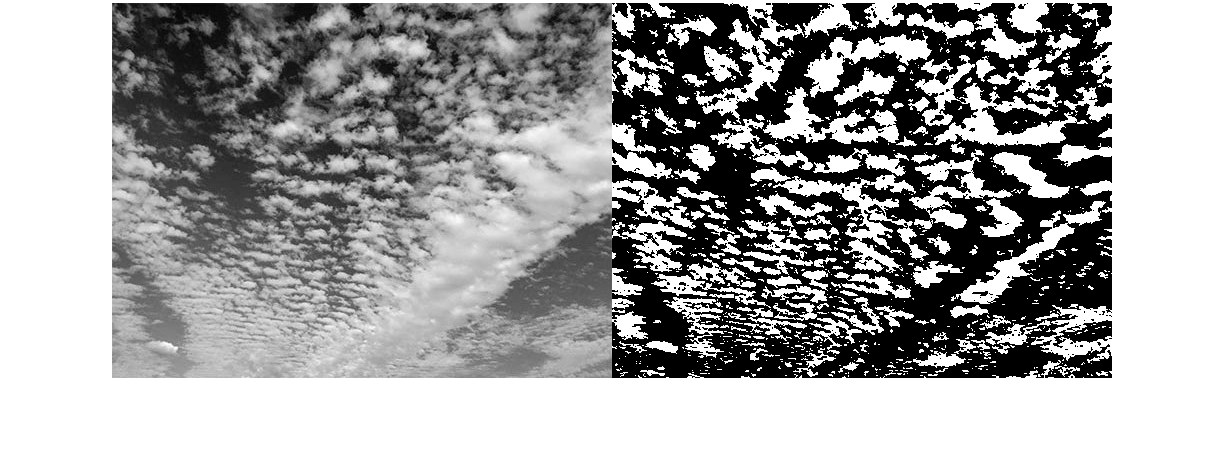

I = rgb2gray(imread('image2.jpg'));
BW = imbinarize(I,'adaptive','Sensitivity',0.55);
imshowpair(I,BW,'montage')


wheter = sum(BW,'all')/numel(BW)*100

wheter = 36.4416

if wheter <= 10
    disp("快晴です！")
elseif wheter <= 80
    disp("晴れてます！")
else
    disp("曇ってます。。。")
end

晴れてます！


% 境界線算出
I = rgb2gray(imread('image2.jpg'));
J = filter2(fspecial('sobel'),I);
min_matrix = min(J(:))

min_matrix = -775

max_matrix = max(J(:))

max_matrix = 866

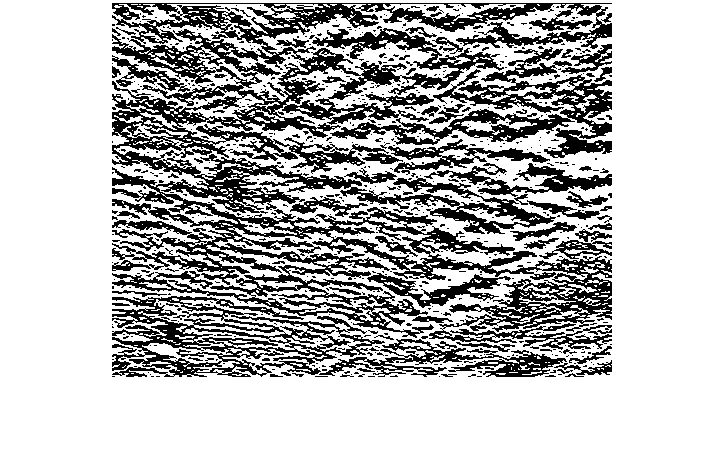

figure
imshow(J)

K = mat2gray(J);
min_image = min(K(:))

min_image = 0

max_image = max(K(:))

max_image = 1

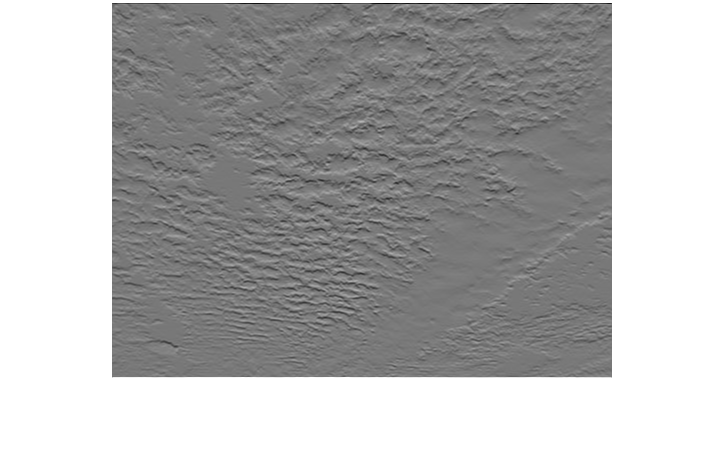

figure
imshow(K)